cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year9')
load Year9_Processed_KF.mat

% demonstrate changes with and without processing using cast 13

cast13ucomp = readSBScnv( 'uar69-01_013_forcomp.cnv' );
cast13dcomp = readSBScnv( 'dar69-01_013_forcomp.cnv' );

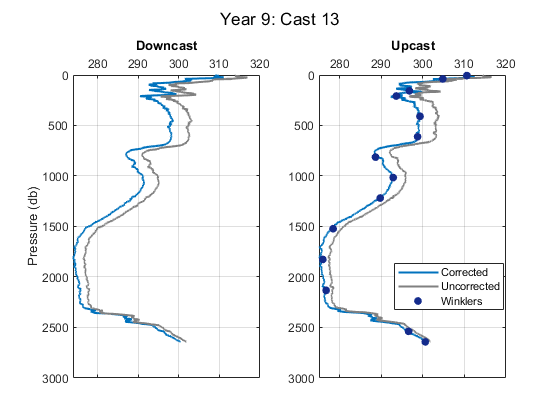


figure
ax1 = subplot(1,2,1);
plot(cast13d.DOcorr_umolkg,cast13d.prs,'Linewidth',1.5,'Color',blue)
hold on
plot(cast13dcomp.sbeox0mL_L*44.661.*cast13dcomp.rho0/1000,cast13dcomp.pm,'Linewidth',1.5,'Color',grey)
axis ij
grid on
title('Downcast')
ax1.XAxisLocation = 'top';
ylabel('Pressure (db)')

ax2 = subplot(1,2,2);
plot(cast13u.DOcorr_umolkg,cast13u.prs,'Linewidth',1.5,'Color',blue)
axis ij
hold on
plot(cast13ucomp.sbeox0mL_L*44.661.*cast13ucomp.rho0/1000,cast13ucomp.pm,'Linewidth',1.5,'Color',grey)
plot(btlsum13.Winkler_umolkg,btlsum13.prs,'.','Markersize',20,'Color',navy)
grid on
ax2.XAxisLocation = 'top';
legend('Corrected','Uncorrected','Winklers','Location','best')
title('Upcast')
sgtitle('Year 9: Cast 13')


cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year4')

load Year4_Processed_KF.mat


% demonstrate changes with and without processing using cast 11

cast11ucomp = readSBScnv( 'uAR21_011_forcomp.cnv' );
cast11dcomp = readSBScnv( 'dAR21_011_forcomp.cnv' );


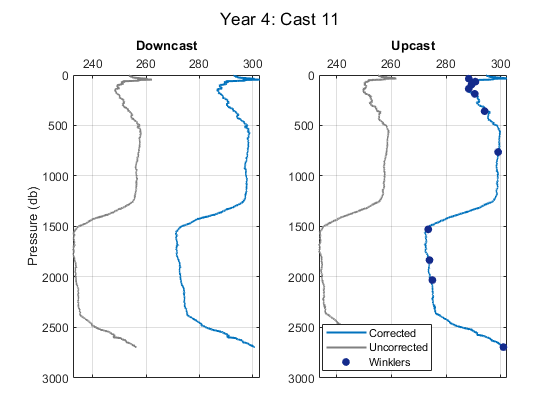


figure
ax1 = subplot(1,2,1);
plot(cast11d.DOcorr_umolkg,cast11d.prs,'Linewidth',1.5,'Color',blue)
hold on
plot(cast11dcomp.sbeox0mL_L*44.661.*cast11dcomp.rho0/1000,cast11dcomp.pm,'Linewidth',1.5,'Color',grey)
axis ij
grid on
title('Downcast')
ax1.XAxisLocation = 'top';
ylabel('Pressure (db)')

ax2 = subplot(1,2,2);
plot(cast11u.DOcorr_umolkg,cast11u.prs,'Linewidth',1.5,'Color',blue)
axis ij
hold on
plot(cast11ucomp.sbeox0mL_L*44.661.*cast11ucomp.rho0/1000,cast11ucomp.pm,'Linewidth',1.5,'Color',grey)
plot(btlsum11.Winkler_umolkg,btlsum11.prs,'.','Markersize',20,'Color',navy)
grid on
ax2.XAxisLocation = 'top';
legend('Corrected','Uncorrected','Winklers','Location','best')
title('Upcast')
sgtitle('Year 4: Cast 11')